# JetBotをROSを使って遠隔操作し、学習画像収集

## 初期化

clear; close all; clc;

## JetBot上のROSノードを起動

launchJetBotROSNode;

## JetBot上のROSに接続

rosshutdown;
load('jetsonIpAddr.mat');
rosinit(jetsonIpAddr); 

## JetBotを制御する用のMATLABGUIを起動

**'s'キーでカメラ画像を動画として保存。**

jetBotKeyboardControl;

## JetBotを制御する用のSimulinkモデルを起動

open_system('ros_teleop');

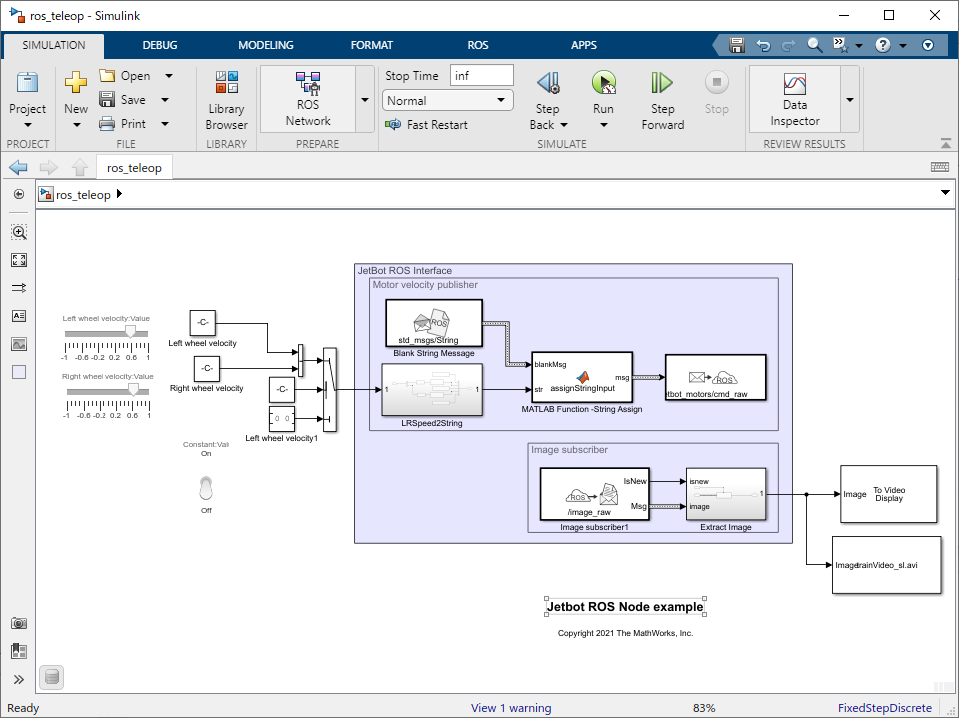

「シミュレーション」タブの「ROSネットワーク」を選択し、「ネットワークアドレス」を「カスタム」に変更、さらに「ホスト名/IPアドレス」を接続先のJetBotのIPアドレスに変更する

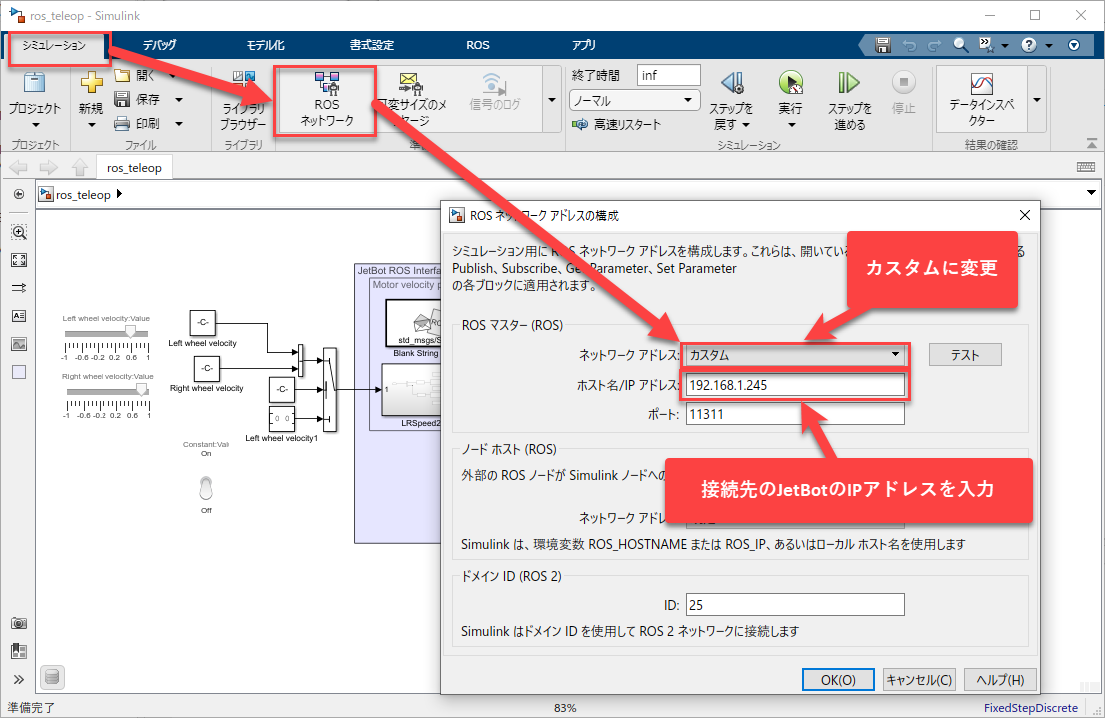

## ROS接続を切断

rosshutdown

## JetBot上のROSノードを停止

stopJetBotROSNode;

*Copyright 2021 The MathWorks, Inc.*